SIA_st.name='SIA'; 
SIA_st.lat=34.09;
SIA_st.lon=-110.94;
SIA_st.alt=1600;

SIA_rd=read_betsy('sierraancha_head',SIA_st.name);

datevec(SIA_rd.Time(1))

ans =         2000           7           2           0           0           0

datevec(SIA_rd.Time(end))

ans =         2010           7           1           0           0           0

prctile(SIA_rd.U_S,[5, 50, 95])

ans =    13.3760   38.5375   88.0480

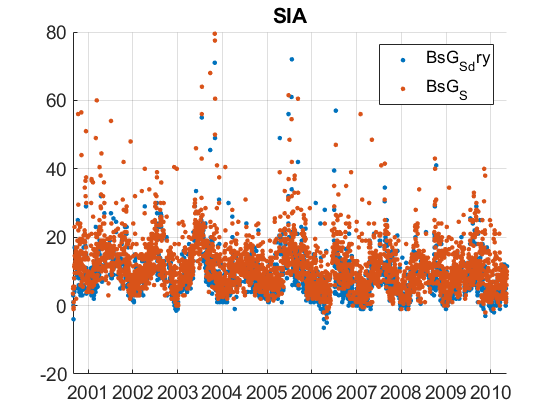

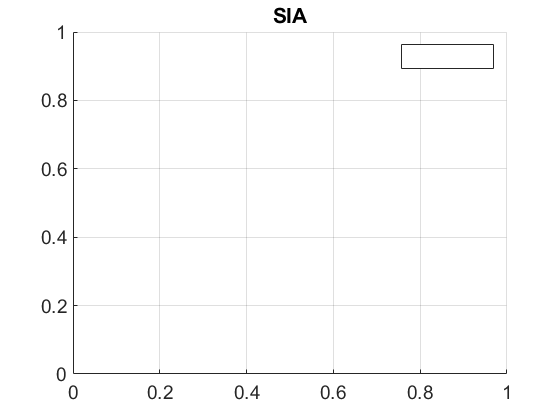

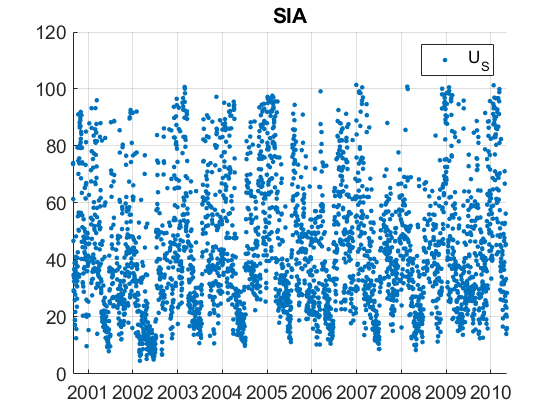

plotFigControl(SIA_rd,SIA_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer-autumn, some negatives

% lambdaSC=[450;550;700]*ones(1,4); % lambdaAE3=[467;530;660]*ones(1,4); % lambdaAE7=[370 470 520 590 660 880 950]; % SIA_cal=compute_exp_SSA(SIA_rd,lambdaSC, lambdaAE3); % plotFigControl_cal(SIA_cal, SIA_st.name);

%Questions:
%problems:
%rupture in June 2006 ??

SIA_t=timetable(SIA_rd.Time);
% begin at the beginning of a year:2001
%end year: 2009
%ONLY 9 y


% dry: OK
%otherwise seems ok